# Modelado dinámico en Biología Sintética

Yadira Boada

05/03/2022

## Modelado de la expresion genética

### Ecuaciones diferenciales con Matlab

Recordemos comando ode45. Su estructura es la siguiente.

%[t,X] = ode45(@(t,x) modelo(t,x,params),tspan,x0,options);

donde:

`t` es la variable independiente

`x` es la variable (o vector de variables) dependientes 

`modelo` es el nombre de la función que da la ecuación diferencial,

`params` contiene valores de parámetros

`tspan` indica el tiempo durante el cual se quiere obtener la solución,

`x0` representa las condiciones iniciales,

`options` las opciones del algoritmo integrador.

### Expresión Constitutiva 

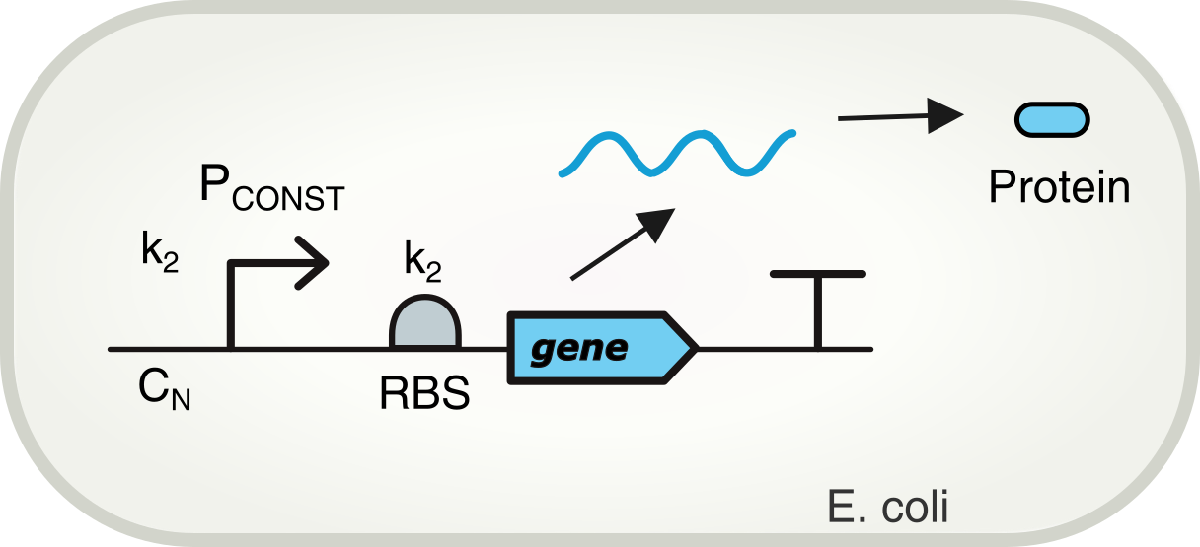

Recordemos que la expresión constitutiva viene dada por las ecuaciones de mRNA (m) y proteína (p):


$$\frac{dm}{dt}=k_1 C_N -d_1m\\
\frac{dp}{dt}=k_2 m -d_2 p$$


Ir al final de este documeto para ver la definición de la función.

**Programa principal**

%  Constitutive Gene expression
%   Parameters: structure contains all rates and constants
%   Updated 05/03/2022 by YB, AV

clear
    %Parameters
    p.CN = 17;        % plasmid number  pACYC184 (17 copies/cell)  
    p.d1 = log(2)/3;  % mRNA degradation rate  [1/min]
    p.d2 = 0.02;      % degradation rate [1/min]
    p.k2 = 8.23;      % translation rate  [1/min] 
    p.k1 = 1.19;      % transcription rate [1/min] 
    

tfin = 60*3;   %simulation final time (en minutos, dado por las tasas)
step = 0.1;    %simulation step
tspan = 0:step:tfin-step; 

%options for ode function
opti = odeset('AbsTol',1e-8,'RelTol',1e-6);      
Init = [0 0];  %initial conditions

[t0,x0] = ode23t(@(t,x) model_const(t,x,p),tspan, Init, opti);

%convert time to hour
time = t0./60;

Gene = ones(1800,1).*p.CN;

Finalmente, representamos gráficamente la solución.

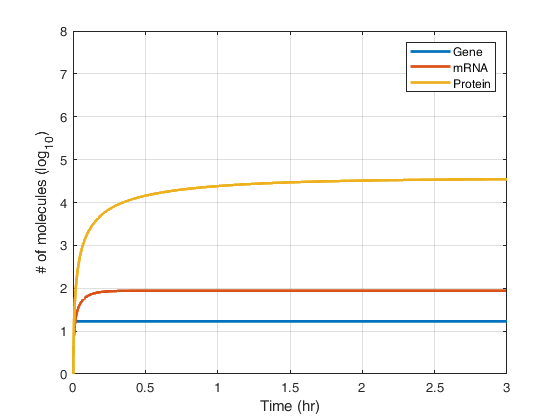

%Plot the simulation results
figure1 = figure('Color',[1 1 1]); 
plot(time,log10(Gene),'LineWidth',2);

hold on;

plot(time,log10(x0(:,1)),'LineWidth',2);

plot(time,log10(x0(:,2)),'LineWidth',2); 
ylabel({'# of molecules (log_{10})'});
xlabel('Time (hr)')
legend('Gene','mRNA','Protein')
ylim([0 8]) 
grid on;

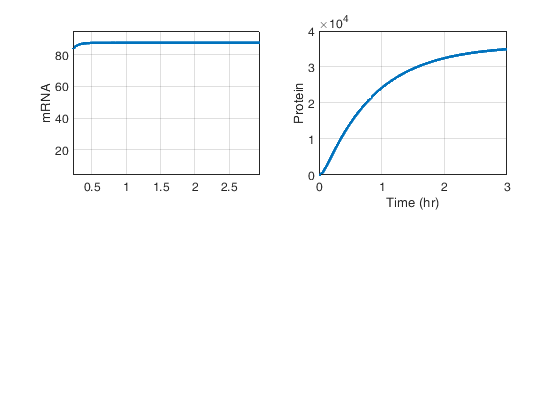


%Plots
 figure1 = figure('Color',[1 1 1]); 
 subplot(221)
 plot(time,(x0(:,1)),'LineWidth',2);
 ylabel('mRNA (molecules)')
 xlabel('Time (hr)')
grid on
subplot(222) 
 plot(time,(x0(:,2)),'LineWidth',2);
 xlabel('Time (hr)')
ylabel('Protein (molecules)')
grid on

function [dxdt] = model_const(t,x,p) %Modelo ODE
%x1 = mRNA
dxdt(1,1) = p.CN*p.k1-p.d1*x(1);
%x2 = Protein
dxdt(2,1) = p.k2*x(1)-p.d2*x(2);
end